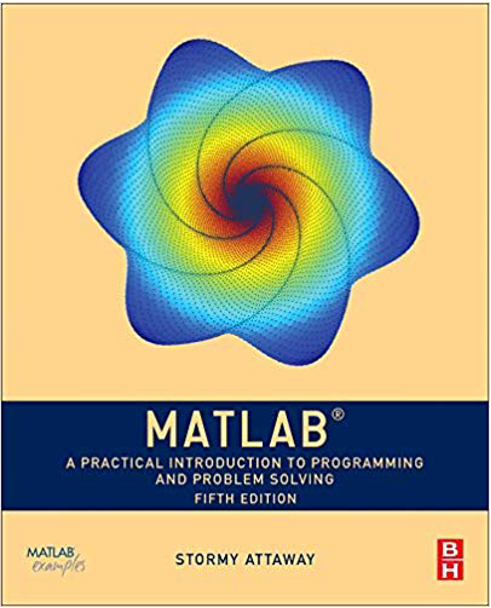

# [Download PDF](https://drive.google.com/file/d/1040KkUSgywtCdBVcLzWHwUlYhgqQd3sV/view?usp=sharing)

# BASIC

- `01 `[`abs`](https://www.mathworks.com/help/matlab/ref/abs.html?s_tid=srchtitle)

- `02 `[`rand`](https://www.mathworks.com/help/matlab/ref/rand.html?searchHighlight=rand&s_tid=srchtitle)

- `03 `[`randn`](https://www.mathworks.com/help/matlab/ref/randn.html?searchHighlight=randn&s_tid=srchtitle)

- `04 `[`randi`](https://www.mathworks.com/help/matlab/ref/randi.html?searchHighlight=randi&s_tid=srchtitle)

- `05 `[`xor`](https://www.mathworks.com/help/matlab/ref/xor.html?searchHighlight=xor&s_tid=srchtitle)

- `06 `[`fix`](https://www.mathworks.com/help/matlab/ref/fix.html?searchHighlight=fix&s_tid=srchtitle)

- `07 `[`floor`](https://www.mathworks.com/help/matlab/ref/floor.html?searchHighlight=floor&s_tid=srchtitle)

- `08 `[`ceil`](https://www.mathworks.com/help/matlab/ref/ceil.html?searchHighlight=ceil&s_tid=srchtitle)

- `09 `[`round`](https://www.mathworks.com/help/matlab/ref/round.html?searchHighlight=round&s_tid=srchtitle)

- `10 `[`mod`](https://www.mathworks.com/help/matlab/ref/mod.html?searchHighlight=mod&s_tid=srchtitle)

- `11 `[`rem`](https://www.mathworks.com/help/matlab/ref/rem.html?searchHighlight=rem&s_tid=srchtitle)

- `12 `[`sqrt`](https://www.mathworks.com/help/matlab/ref/sqrt.html?searchHighlight=sqrt&s_tid=srchtitle)

- `13 `[`Log`](https://www.mathworks.com/help/matlab/ref/log.html?searchHighlight=Log&s_tid=srchtitle)

- `14` [`disp`](https://www.mathworks.com/help/matlab/ref/disp.html?searchHighlight=disp&s_tid=srchtitle)

1.1 + 2.2 

ans = 3.3000

1.1 + 2.2 == 3.3      % Logical 1 (true)   % Logical 0 (false)

ans = logical
   0


% why !?!  

`Solution :`

tolerance = 0.0000000000001 ;   % Error determination  Ex : 1e-10
abs(1.1 + 2.2 - 3.3) < tolerance    

ans = logical
   1


# `01 . abs `

  $\to \;$ `Absolute value and complex magnitude`

abs(-3)

ans = 3

-abs(3)

ans = -3

abs(3+4i)        % sqrt(3^2 + 4^2)

ans = 5

# `02 . rand`

 →`  Uniformly distributed random numbers`

r_1 = rand(3)               % Generate a 3-by-3 matrix of uniformly distributed random numbers between 0 and 1.

r_1 =     0.2653    0.7302    0.1078
    0.8244    0.3439    0.9063
    0.9827    0.5841    0.8797


r_2 = -10 + (20)*rand(3,1)  %Generate a 3-by-1 column vector of uniformly distributed numbers in the interval (-10,10).

r_2 =     6.3552
   -4.7854
    1.8871


r_3 = -10 + (20)*rand(1,3)  %Generate a 3-by-1 column vector of uniformly distributed numbers in the interval (-10,10).

r_3 =    -9.5497   -1.4948   -3.7456


# `03 . randn`

 →`  Normally distributed random numbers`

r_4 = randn(3)

r_4 =    -1.0257   -1.6989    0.6992
   -0.9087    0.6076    0.2696
   -0.2099   -0.1178    0.4943


# `04 . randi`

→`  Uniformly distributed pseudorandom integers`

% Generate a 2-by-2 matrix of random integers between 1 and 10. 
% The first input to randi indicates the largest integer in the sampling interval (the smallest integer in the interval is 1).
r_5 = randi(10,2)

r_5 =      1     4
     1     6


% Generate a 5-by-1 column vector of uniformly distributed random integers from the sample interval [-10,10].
r_6 = randi([-10,10],5,1)

r_6 =      3
    -2
     7
     5
    10


% random number generator and create a 1-by-4 vector of random integers.
r_7 = randi(10,1,4)

r_7 =      6     4     2     7


# `05 . xor`

→` Find logical exclusive-OR`

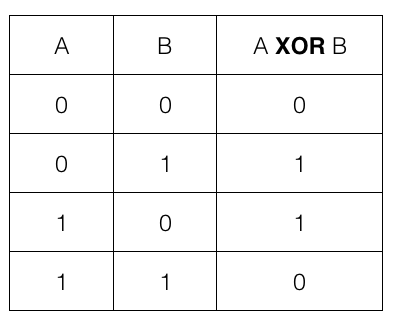

A_temp = [true ]     % Logical 1 (true)   % Logical 0 (false)

A_temp = logical
   1


B = [true ]          % Logical 1 (true)   % Logical 0 (false)

B = logical
   1


xor(A_temp,B)

ans = logical
   0


# `06 . fix`

→` Round toward ``zero`

r_8 = [-1.9  -3.4  10.6   -20.5  -14.5   5.5];
fix(r_8)

ans =     -1    -3    10   -20   -14     5


# `07 . floor`

→` Round toward ``negative infinity`

r_9 = [-1.9  -3.4  10.6   -20.5  -14.5   5.5];
floor(r_9)

ans =     -2    -4    10   -21   -15     5


# `08 . ceil`

→` Round toward ``positive infinity`

r_10 = [-1.9  -3.4  10.6   -20.5  -14.5   5.5];
ceil(r_10)

ans =     -1    -3    11   -20   -14     6


# `09 . round`

→  Round to nearest decimal or integer

r_11 = [-1.9  -3.4  10.6   -20.5  -14.5   5.5];
round(r_11)

ans =     -2    -3    11   -21   -15     6


# `10 . mod`

`- Remainder after division (modulo operation)`

→`  b = mod(a,m) `⟶  `b = a - m.*floor(a./m)`

mod(10,2)

ans = 0

r_12 = [ 10   30  10.6   20.5   14.5   5.5   -5.5];
mod(r_12,2)

ans =          0         0    0.6000    0.5000    0.5000    1.5000    0.5000


# `11 . rem`

→  `Remainder after division`

→  `r = rem(a,b) `⟶  `r = a - b.*fix(a./b)`

r_13 = [ 10   30  10.6   20.5   14.5   5.5   -5.5];
rem(r_13,2)

ans =          0         0    0.6000    0.5000    0.5000    1.5000   -1.5000


# ` - rem or mod ?!?`

- `Type 1`


rem(4, 2)

ans = 0


mod(4, 2)

ans = 0

- `Type 2`

rem(-4 ,-3)

ans = -1

mod(-4 ,-3)

ans = -1

- `Type 3`

rem(4 ,-3)

ans = 1

mod(4 ,-3)

ans = -2

- `Type 4`

rem(-4 ,3)

ans = -1

mod(-4 ,3)

ans = 2

# `12 . sqrt (`$\sqrt{}$`)`

r_14 = [ 100   30  10.6   20.5   14.5   5.5   -5.5];
sqrt(r_14)

ans =   10.0000 + 0.0000i   5.4772 + 0.0000i   3.2558 + 0.0000i   4.5277 + 0.0000i   3.8079 + 0.0000i   2.3452 + 0.0000i   0.0000 + 2.3452i


# `nthroot(`$\sqrt[n]{}$`)`

r_15 = [ 27   30  10.6   20.5   14.5   5.5   -5.5];
nthroot(r_15 ,3 )

ans =     3.0000    3.1072    2.1967    2.7369    2.4385    1.7652   -1.7652


# `13 . Log`

- `log (Natural logarithm)`

- `log2 Base 2 logarithm and floating-point number dissection`

- `log10 Common logarithm (base 10)`

- `exp (Exponential)`

- `deg2rad Convert angle from ``degrees`` to(2)! ``radians`

- `rad2deg Convert angle from ``radians`` to(2)! ``degrees`

log(10)

ans = 2.3026

log2(10)

ans = 3.3219

log10(10)

ans = 1

exp(10)

ans = 2.2026e+04

deg2rad(45)

ans = 0.7854

rad2deg(45)

ans = 2.5783e+03

# `Exercises`

temp_f = 75;
temp_c = (temp_f - 32) * 5/9 

temp_c = 23.8889

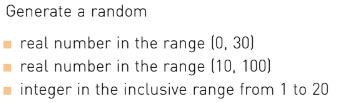

%1
30 * rand 

ans = 23.3641

%2
10+ rand*(100 - 10) 

ans = 48.1108

%3
randi(20)

ans = 2

%4
randi([0, 20])

ans = 5

%5
randi([30, 80])

ans = 37

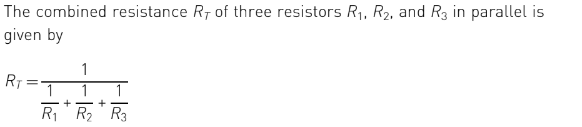

r1 = 2;
r2 = 3;
r3 = 4;
rt = 1/((1/r1) + (1/r2) + (1/r3))

rt = 0.9231

# `14 . disp`

→  `Display value of variable`

A_temp = 2;
disp(A_temp)

     2



S_temp = 'Hello Korosh Agha Mohammad Ghasemi.  :))) ';
disp(S_temp)

Hello Korosh Agha Mohammad Ghasemi.  :))) 


# 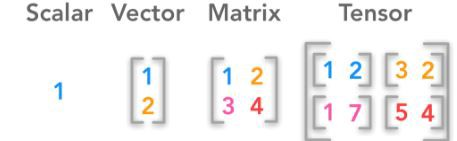

# `Vectors`

- `00 BASIC`

- `01 `[linspace](https://www.mathworks.com/help/matlab/ref/linspace.html?searchHighlight=linspace&s_tid=srchtitle)

- `02 `[`logspace`](https://www.mathworks.com/help/matlab/ref/logspace.html)

- `03 `[`length`](https://www.mathworks.com/help/matlab/ref/length.html?searchHighlight=length&s_tid=srchtitle)

- `04 `[`fliplr`](https://www.mathworks.com/help/matlab/ref/fliplr.html?searchHighlight=fliplr&s_tid=srchtitle)

- `05 `[`min & max`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle)

- `06 `[`sum & prod`](https://www.mathworks.com/help/matlab/ref/prod.html?searchHighlight=prod&s_tid=srchtitle)

- `07 `[`cumsum & cumprod`](https://www.mathworks.com/help/matlab/ref/cumprod.html)

- `08 `[`cummin & cummax`](https://www.mathworks.com/help/matlab/ref/cummax.html)

- `09 `[`find`](https://www.mathworks.com/help/matlab/ref/find.html?searchHighlight=find&s_tid=srchtitle)

- `10 `[isequal](https://www.mathworks.com/help/matlab/ref/isequal.html?searchHighlight=isequal&s_tid=srchtitle)

- `11 `[isprime](https://www.mathworks.com/help/matlab/ref/isprime.html?searchHighlight=isprime&s_tid=srchtitle) 

# `00 . BASIC`

a_0 = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15]

a_0 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


a_01 = [1:15]

a_01 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


a_02 = [1:2:15]   % x1, step, x2.

a_02 =      1     3     5     7     9    11    13    15


a_02(4)    % index

ans = 7

a_02(2:4)   % index

ans =      3     5     7


% a_02(0)  and  a_02(-1)  ------> Error

# `01 . linspace`

                                   $\to \;\;$`Generate linearly spaced vector`

a_1 = linspace(-1, 3)     % a row vector of 100 evenly spaced points between x1 and x2.

a_1 =    -1.0000   -0.9596   -0.9192   -0.8788   -0.8384   -0.7980   -0.7576   -0.7172   -0.6768   -0.6364   -0.5960   -0.5556   -0.5152   -0.4747   -0.4343   -0.3939   -0.3535   -0.3131   -0.2727   -0.2323   -0.1919   -0.1515   -0.1111   -0.0707   -0.0303    0.0101    0.0505    0.0909    0.1313    0.1717    0.2121    0.2525    0.2929    0.3333    0.3737    0.4141    0.4545    0.4949    0.5354    0.5758    0.6162    0.6566    0.6970    0.7374    0.7778    0.8182    0.8586    0.8990    0.9394    0.9798


a_2 = linspace(-1, 3, 10)    % The spacing between the points is (x2 - x1)/(n-1).

a_2 =    -1.0000   -0.5556   -0.1111    0.3333    0.7778    1.2222    1.6667    2.1111    2.5556    3.0000


# `02 . logspace`

                   $\to \;\;$`Generate logarithmically spaced vector`

a_3 = logspace(1, 3)  % a row vector y of 50 logarithmically spaced points between decades 10^a and 10^b.

a_3 = 	1.0e+03 *

    0.0100    0.0110    0.0121    0.0133    0.0146    0.0160    0.0176    0.0193    0.0212    0.0233    0.0256    0.0281    0.0309    0.0339    0.0373    0.0409    0.0450    0.0494    0.0543    0.0596    0.0655    0.0720    0.0791    0.0869    0.0954    0.1048    0.1151    0.1265    0.1389    0.1526    0.1677    0.1842    0.2024    0.2223    0.2442    0.2683    0.2947    0.3237    0.3556    0.3907    0.4292    0.4715    0.5179    0.5690    0.6251    0.6866    0.7543    0.8286    0.9103    1.0000


a_4 = logspace(1, 6, 2)  % generates n points between decades 10^a and 10^b.

a_4 =           10     1000000


#  . . .

# `03 . length`

                $\to \;\;$`Length of largest array dimension`

length(a_4)

ans = 2

length(a_0)

ans = 15

a_5 = ' Korosh Agha Mohammad Ghasemi ' ;  % string
length(a_5)

ans = 30

a_5(5)

ans = 'o'

% why!?!   'o'  or 's'  ?!?!     Solution : Space   :))


# `04 . fliplr`

                          $\to$  Flip array left to right

fliplr(a_0)

ans =     15    14    13    12    11    10     9     8     7     6     5     4     3     2     1


fliplr(a_5)

ans = ' imesahG dammahoM ahgA hsoroK '

# `05 . min & max`

max(a_1)

ans = 3

min(a_1)

ans = -1

# `06 . sum & prod`

a_6 = [1, 3, 5, 7] ;
sum(a_6)

ans = 16

prod(a_6)    % 1 * 3 * 5 * 7

ans = 105

(1*3*5*7)

ans = 105

# `07 . cumsum & cumprod`

cumsum(a_6)

ans =      1     4     9    16


cumprod(a_6)

ans =      1     3    15   105


# `08 . cummin & cummax`

a_6 = [1, 3, 5, 7] ;
cummin(a_6)

ans =      1     1     1     1


cummax(a_6)

ans =      1     3     5     7


# `09 . find`

a_6 = [1, 3, 5, 7] ;
a_6 == 3

ans = 1×4 logical array
   0   1   0   0


find(a_6 == 3)

ans = 2

find(a_6 ~= 3)  % 1 

ans =      1     3     4


a_6(find(a_6 ~= 3))  % 1 

ans =      1     5     7


find(a_6 < 5)    % 2    % a_6(find(a_6 < 5))

ans =      1     2


a_6(a_6 < 5)  % 2       % a_6(find(a_6 < 5))

ans =      1     3


# `10 . isequal  (==)`

a_6 = [1, 3, 5, 7] ;
a_7 = [2, 4, 6, 8] ;
a_8 = [1, 3, 5, 7] ;
isequal(a_7, a_6)

ans = logical
   0


isequal(a_8, a_6)

ans = logical
   1


# `11 . isprime`

a_7 = [2, 4, 6, 8] ;
isprime(a_7)

ans = 1×4 logical array
   1   0   0   0


a_7(isprime(a_7))

ans = 2

# 

 % 20 = {1, 2, 4, 5, 10, 20}

#### `.1`

N = 20 ;
x = 1:N ;
M = x(~(rem(N,x)))

M =      1     2     4     5    10    20


#### `.2`

s = sum(M(isprime(M)))

s = 7

# `Matrices`

# 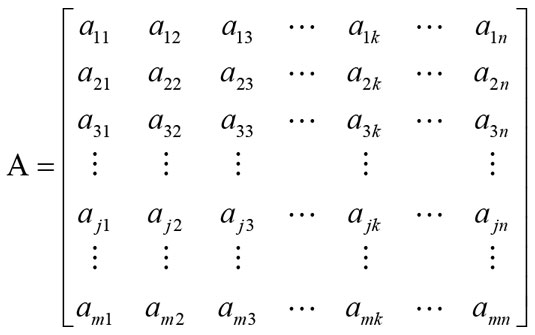

a_8 = [1, 2, 3, 4, 5, 6]

a_8 =      1     2     3     4     5     6


a_9 = [1; 2; 3; 4; 5; 6]

a_9 =      1
     2
     3
     4
     5
     6


a_10 = [1, 2, 3; 4, 5, 6]

a_10 =      1     2     3
     4     5     6


% best solution
a_11 = [
      1,  2,  3;
      4,  5,  6;
    ]

a_11 =      1     2     3
     4     5     6


# `Change rows and columns`

a_12 = [
      0,  2,  3,  4,  5,  6;
      7,  8,  9, 10, 11, 12;
     13, 14, 15, 16, 17, 18;
     19, 20, 21, 22, 23, 24;
     25, 26, 27, 28, 29, 30;
     31, 32, 33, 34, 35, 36
   ]

a_12 =      0     2     3     4     5     6
     7     8     9    10    11    12
    13    14    15    16    17    18
    19    20    21    22    23    24
    25    26    27    28    29    30
    31    32    33    34    35    36


list = [2 4]

list =      2     4


a_12(list,:) = []

a_12 =      0     2     3     4     5     6
    13    14    15    16    17    18
    25    26    27    28    29    30
    31    32    33    34    35    36


a_12(:,list) = []

a_12 =      0     3     5     6
    13    15    17    18
    25    27    29    30
    31    33    35    36


a_12(:,[2 1 3 4])

ans =      3     0     5     6
    15    13    17    18
    27    25    29    30
    33    31    35    36


a_12([2 1 3 4], :)

ans =     13    15    17    18
     0     3     5     6
    25    27    29    30
    31    33    35    36


# `Exercises`

% 2 + 4 + 6 + 8 + 10 = 30 !!!!!!!!!!!!!!!!!!!!!!   :(((((((
a_120 = (2:2:10)

a_120 =      2     4     6     8    10


a_121 = sum(2:2:10)     % :)))))

a_121 = 30

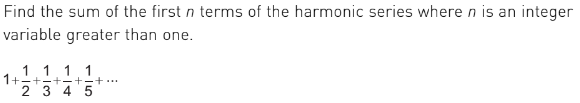

% type 1
k = 1./(1:5)

k =     1.0000    0.5000    0.3333    0.2500    0.2000


sum(k)

ans = 2.2833

% type 2
a_13 = [1] ;
a_14 = [1:1:5] ;
a_15 = a_13./a_14 

a_15 =     1.0000    0.5000    0.3333    0.2500    0.2000


sum(a_15)

ans = 2.2833

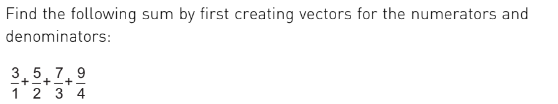

a_16 = (3:2:9)

a_16 =      3     5     7     9


a_17 = (1:4)

a_17 =      1     2     3     4


a_18 = a_16./a_17

a_18 = 1×4
    3.0000    2.5000    2.3333    2.2500


sum(a_18)

ans = 10.0833

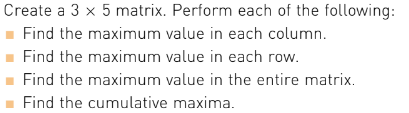

a_19 = randi([-10 10], 3, 5)

a_19 = 3×5
    -5    -1     9    -5     4
    -1     8     3     4     4
     1     0    10    -4    -9


% find the max value in each column.
max(a_19)

ans = 1×5
     1     8    10     4     4


% find the min value in each row.
max(a_19, [], 2)

ans = 3×1
     9
     8
    10


max(a_19')

ans = 1×3
     9     8    10


% find the max value in the entire matrix.
max(max(a_19))

ans = 10

% find the cumulative maxima
cummax(a_19)

ans = 3×5
    -5    -1     9    -5     4
    -1     8     9     4     4
     1     8    10     4     4


a_20 = randi([50, 100], 1, 20)

a_20 = 1×20
    62    61    84    93    67    89    84    50    80    69    96    50    73    71    73    89    66    90    74    51


even = a_20(rem(a_20,2) == 0)

evens = 1×10
    62    84    84    50    80    96    50    66    90    74


odd = a_20(rem(a_20,2) ~= 0)

odd = 1×10
    61    93    67    89    69    73    71    73    89    51


`-------------------------------------------------------------------------------------------`

`. `[`Korosh Agha Mohammad Ghasemi `](https://koroshkorosh1.github.io/korosh.github.io/)`. `